data = readtable('/Users/lynnxt/Desktop/LOB_data.csv');
data

data = 438673×12 table
    MsgType    SeqNumber     Symbol     SourceTime    SymbolSeqnum     OrderID      Price     Volume    Side     FirmID    NumParitySplits    len_firmid
    _______    _________    ________    __________    ____________    __________    ______    ______    _____    ______    _______________    __________

      100        12395      {'AAPL'}     07:00:00           4         1.7733e+16     135.2       5      {'B'}     NaN             0               0     
      100        13035      {'AAPL'}     07:00:49           5         1.7733e+16    141.82     100      {'S'}     NaN             0               0     
      100        13061      {'AAPL'}     07:00:55           7         1.7733e+16    141.71     100      {'B'}     NaN             0               0     
      100        13129      {'AAPL'}     07:01:22           9         1.7733e+16    141.76     100      {'S'}     NaN             0               0     
      100        13154      {'AAPL'}     07:01:33         

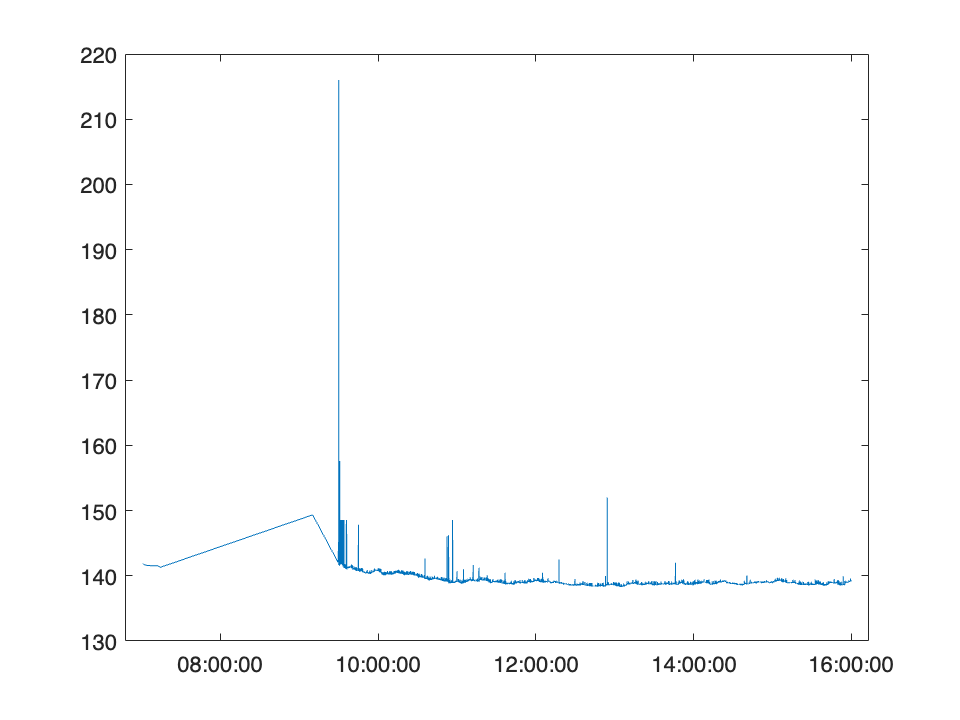


LOB = data(:, {'Price','SourceTime','Volume', 'Side'});

Bid = LOB(strcmp(LOB.Side, 'S'),:);
Ask = LOB(strcmp(LOB.Side, 'B'),:);
%Volume = LOB(strcmp(LOB.Volume),:);
%Price=LOB(strcmp(LOB.Price),:);

% Before data normalization
plt1 = plot(Bid.SourceTime, Bid.Price);

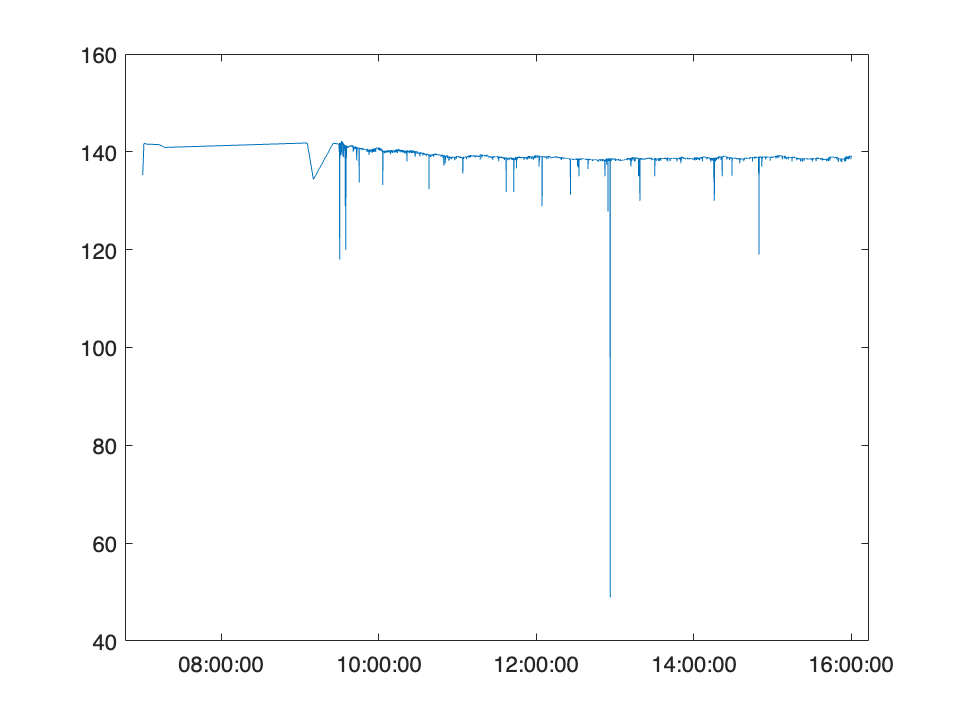

plt2 = plot(Ask.SourceTime, Ask.Price);

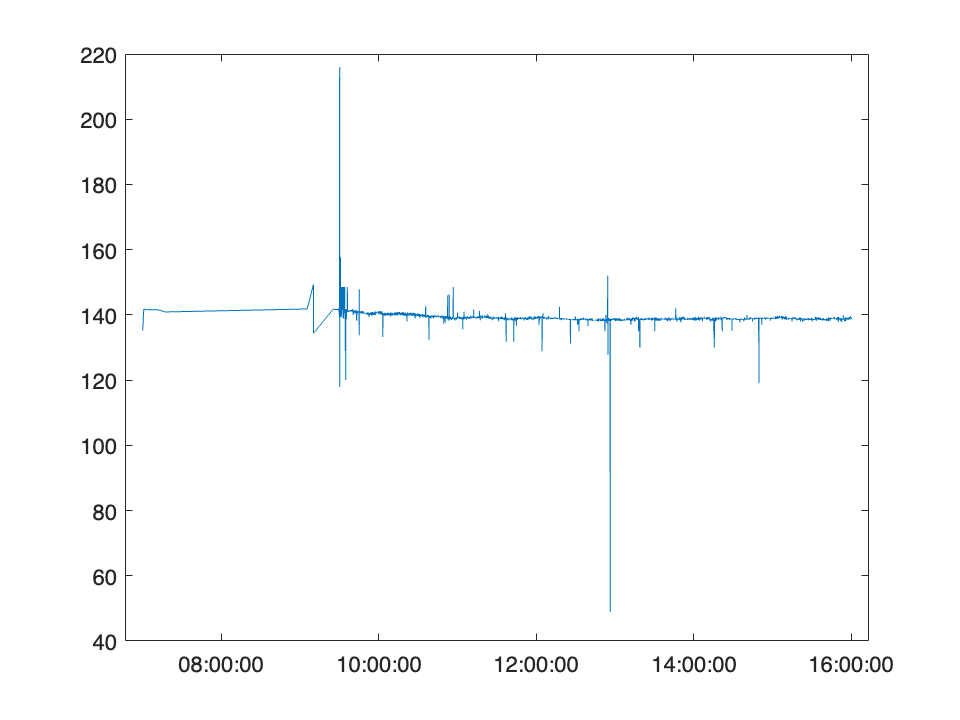

plt3 =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [07:00:00    07:00:49    07:00:55    07:01:22    07:01:33    07:02:35    07:02:37    07:03:08    07:03:10    07:03:47    07:03:49    07:05:14    07:05:14    07:11:37    07:11:47    07:12:59    07:13:53    …    ] (1×438673 duration)
              YData: [135.2000 141.8200 141.7100 141.7600 141.6900 141.6800 141.6700 141.6600 141.5800 141.6100 141.6100 141.5500 141.5600 141.5400 141.4800 141.4400 141.3400 141.3400 141.3100 141.2900 141.3000 140.9000 141.8100 … ] (1×438673 double)

  显示 所有属性


plt3 = plot(LOB.SourceTime, LOB.Price)

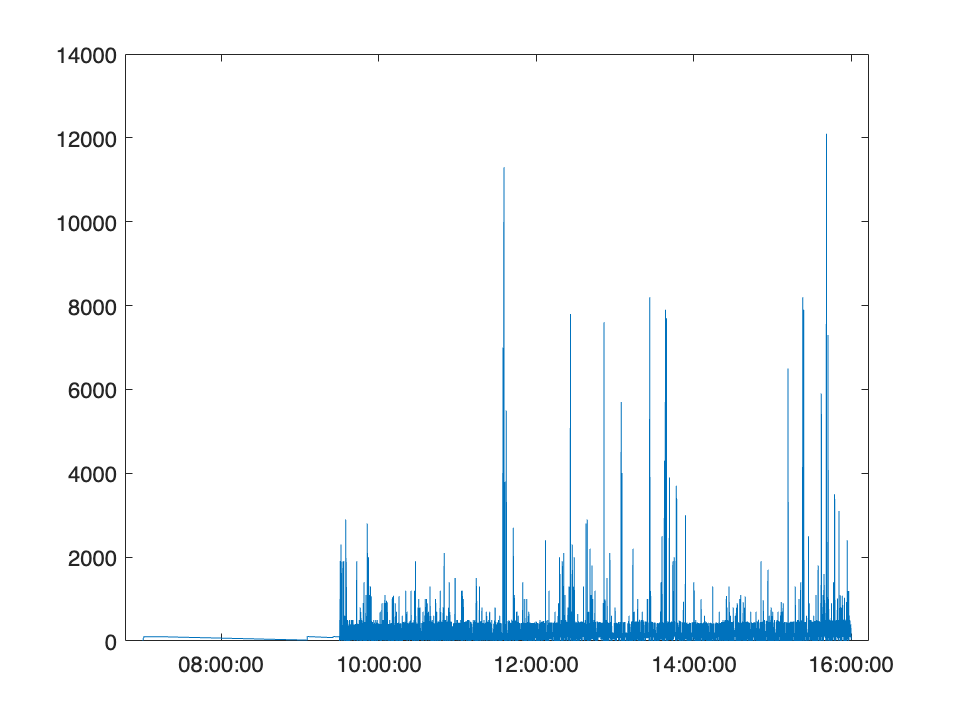

plt4 =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [07:00:00    07:00:49    07:00:55    07:01:22    07:01:33    07:02:35    07:02:37    07:03:08    07:03:10    07:03:47    07:03:49    07:05:14    07:05:14    07:11:37    07:11:47    07:12:59    07:13:53    …    ] (1×438673 duration)
              YData: [5 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 21 80 106 100 100 80 106 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 3 10 300 300 70 70 100 100 100 100 … ] (1×438673 double)

  显示 所有属性

plt4 = plot(LOB.SourceTime, LOB.Volume)

% Data Normalization 
normalizedBid = normalization(Bid);

normalizedLOB = 251105×2 table
    Price      Volume 
    ______    ________

    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064
    2.0264    -0.14064


normalizedAsk = normalization(Ask);

normalizedLOB = 187568×2 table
     Price       Volume  
    _______    __________

     -5.164       -2.2167
     3.2985      -0.13285
     3.1295      -0.13285
     2.9996      -0.13285
     2.7656      -0.13285
     2.2456      -0.13285
     3.4285       -1.8657
     3.4285      -0.57156
     3.4285    -0.0012434
     -6.256      -0.13285
     3.3505      -0.57156
     3.3505    -0.0012434
     3.1295      -0.13285
    0.28269      -0.13285
    -3.2531      -0.13285
     1.2186      -0.13285


normalizedLob=normalization(LOB)

normalizedLOB = 438673×2 table
     Price      Volume 
    _______    ________

    -5.4132     -2.2665
     3.5866    -0.13725
     3.4371    -0.13725
      3.505    -0.13725
     3.4099    -0.13725
     3.3963    -0.13725
     3.3827    -0.13725
     3.3691    -0.13725
     3.2603    -0.13725
     3.3011    -0.13725
     3.3011    -0.13725
     3.2195    -0.13725
     3.2331    -0.13725
     3.2059    -0.13725
     3.1244    -0.13725
       3.07    -0.13725


normalizedLob = 438673×4 table
     Price      Volume     SourceTime    Side 
    _______    ________    __________    _____

    -5.4132     -2.2665     07:00:00     {'B'}
     3.5866    -0.13725     07:00:49     {'S'}
     3.4371    -0.13725     07:00:55     {'B'}
      3.505    -0.13725     07:01:22     {'S'}
     3.4099    -0.13725     07:01:33     {'S'}
     3.3963    -0.13725     07:02:35     {'S'}
     3.3827    -0.13725     07:02:37     {'S'}
     3.3691    -0.13725     07:03:08     {'S'}
     3.2603    -0.13725     07:03:10     {'B'}
     3.3011    -0.13725     07:03:47     {'S'}
     3.3011    -0.13725     07:03:49     {'S'}
     3.2195    -0.13725     07:05:14     {'S'}
     3.2331    -0.13725     07:05:15     {'S'}
     3.2059    -0.13725     07:11:37     {'S'}
     3.1244    -0.13725     07:11:47     {'B'}
       3.07    -0.13725     07:12:59     {'S'}


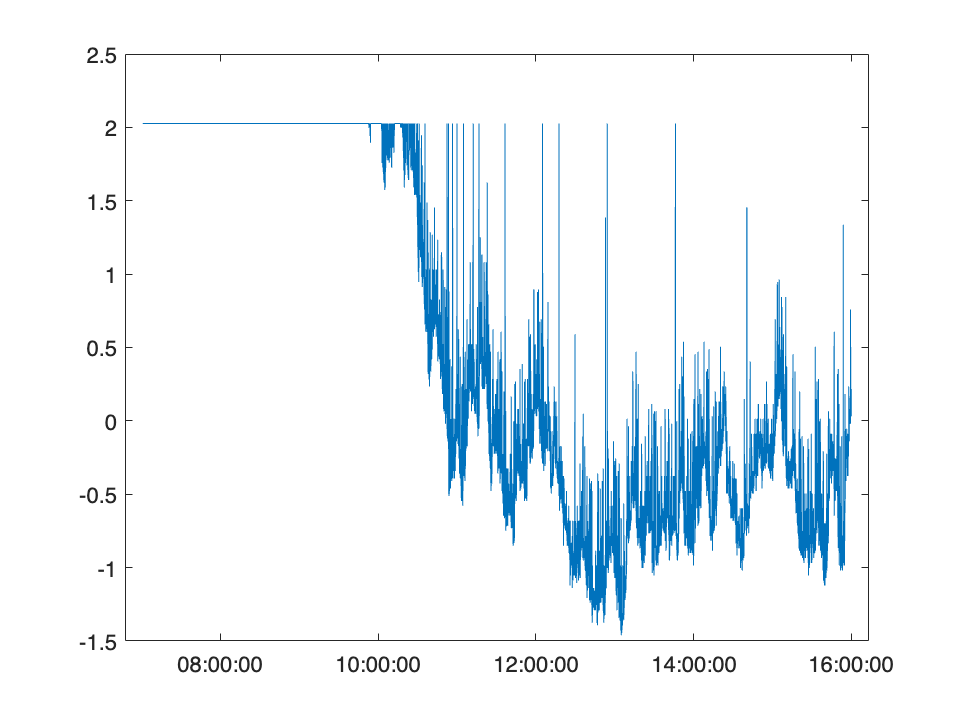

% Before data normalization
plt_1 = plot(normalizedBid.SourceTime, normalizedBid.Price);

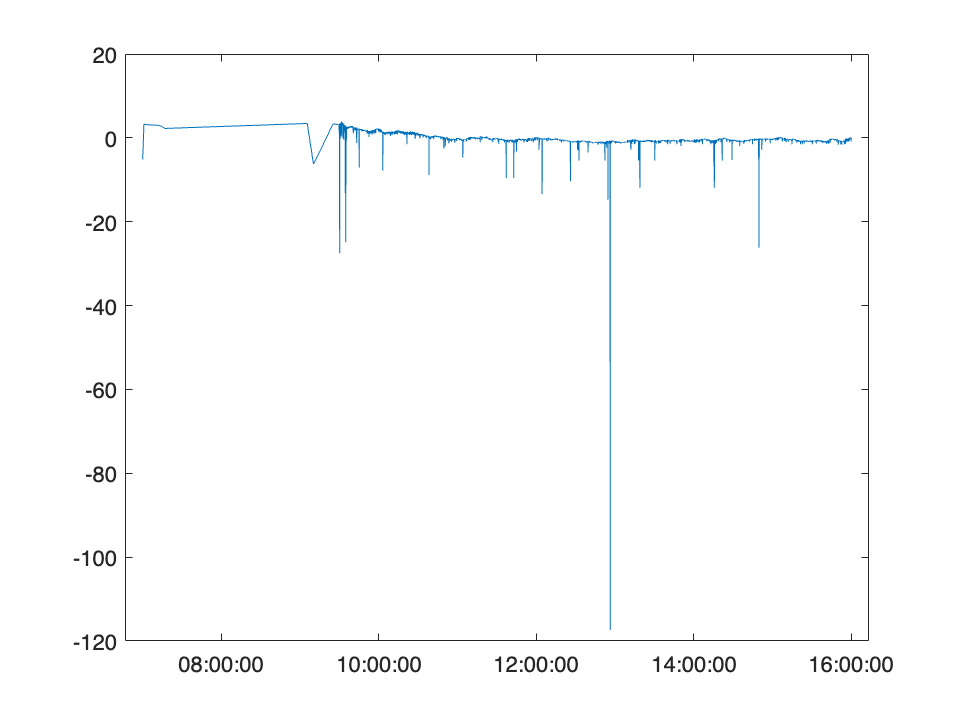

plt_2 = plot(normalizedAsk.SourceTime, normalizedAsk.Price);

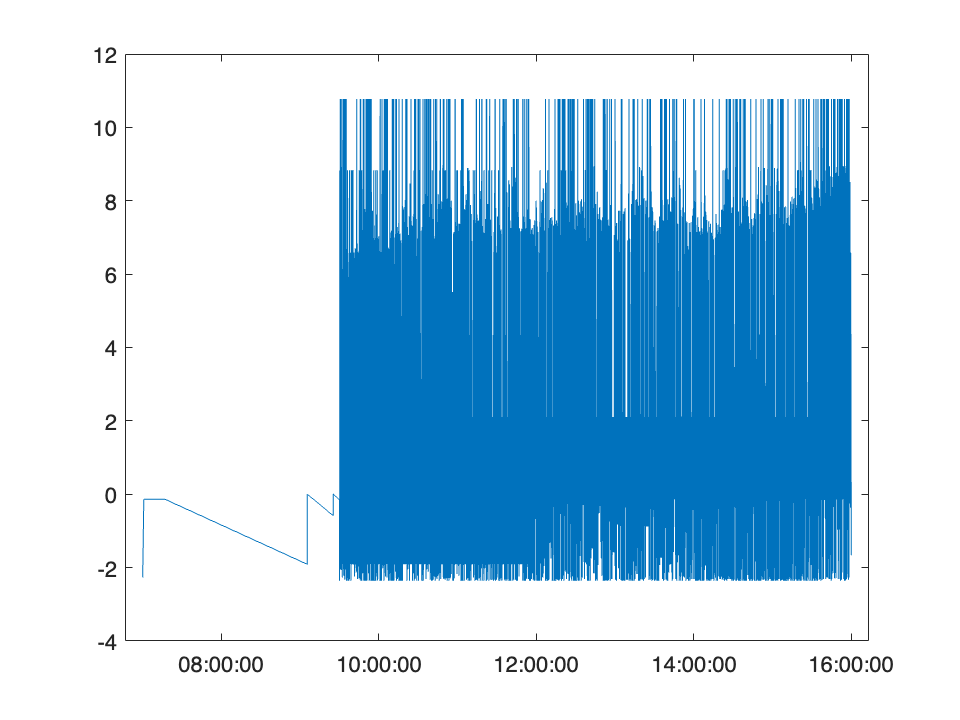

plt_3 =   Line - 属性:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [07:00:00    07:00:49    07:00:55    07:01:22    07:01:33    07:02:35    07:02:37    07:03:08    07:03:10    07:03:47    07:03:49    07:05:14    07:05:14    07:11:37    07:11:47    07:12:59    07:13:53    …    ] (1×438673 duration)
              YData: [-2.2665 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -0.1372 -1.9079 -0.5855 -0.0028 -0.1372 … ] (1×438673 double)

  显示 <a href="matlab:if exist('plt_3', 'var'), matlab.graphics.internal.getForDisplay('plt_3', plt_3, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('plt_3'), end">所有属性<


plt_3 = plot(normalizedLob.SourceTime,normalizedLob.Volume)

%plt_3 = 

% Data Split

function normalizedTable = normalization(data)
 
    % Extract numeric data for normalization
    numericData = table2array(data(:, {'Price', 'Volume'}));

    % Compute Median Absolute Deviation (MAD) for each numeric column
    madValues = mad(numericData);

    % Define a threshold for outliers (e.g., 3 times MAD)
    threshold1 = 260;%260-290
    threshold2 = 25;

    % Replace outliers with MAD for 'Price' column
    priceColumn = numericData(:, 1);
    priceColumn(abs(priceColumn) > threshold1 * madValues(1)) = sign(priceColumn(abs(priceColumn) > threshold1 * madValues(1))) * threshold1 * madValues(1);

    % Replace outliers with MAD for 'Volume' column
    volumeColumn = numericData(:, 2);
    volumeColumn(abs(volumeColumn) > threshold2 * madValues(2)) = sign(volumeColumn(abs(volumeColumn) > threshold2 * madValues(2))) * threshold2 * madValues(2);

    % Update the modified columns in the numericData matrix
    numericData(:, 1) = priceColumn;
    numericData(:, 2) = volumeColumn;

    % Z-score normalization
    normalizedData = zscore(numericData);

    % Create a new table with the normalized and outliers-replaced data
    normalizedLOB = array2table(normalizedData, 'VariableNames', {'Price', 'Volume'});
    normalizedLOB
    % Combine the normalized numeric columns with the non-numeric columns
    normalizedTable = [normalizedLOB, data(:, 'SourceTime'), data(:, 'Side')];
end


